%  ____                                                 
% |  _ \ _ __ ___  _ __   ___                           
% | | | | '__/ _ \| '_ \ / _ \                          
% | |_| | | | (_) | | | |  __/                          
% |____/|_|  \___/|_| |_|\___|         _                
% |  _ \ __ _ _ __ __ _ _ __ ___   ___| |_ ___ _ __ ___ 
% | |_) / _` | '__/ _` | '_ ` _ \ / _ \ __/ _ \ '__/ __|
% |  __/ (_| | | | (_| | | | | | |  __/ ||  __/ |  \__ \
% |_|   \__,_|_|  \__,_|_| |_| |_|\___|\__\___|_|  |___/
%

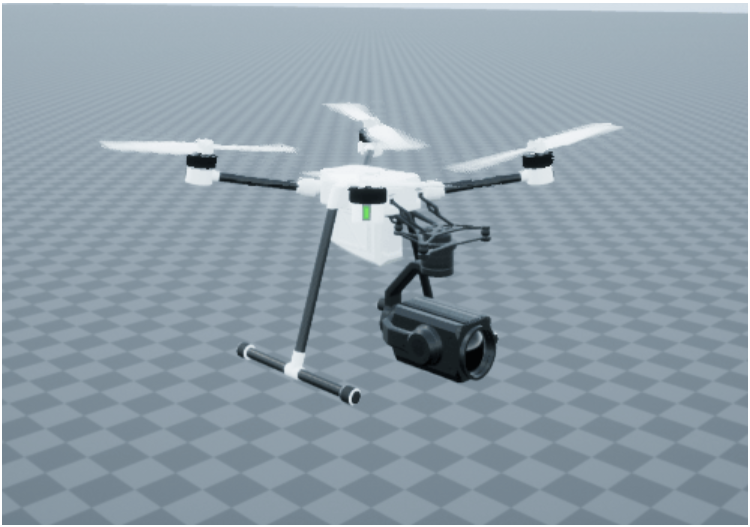   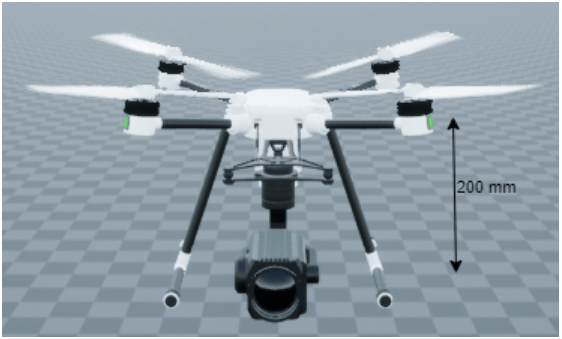

% Paramètres :
g = 9.81;           % [m/s²] gravity
m = 1.375;            % [m] total weight 
L = 0.247;           % [m] 
h = 0.063;           % [m]
z_ground = 0.19;     % [m] drone COM altitude above ground

% Moteurs (propellers)
FMi=13.2;
Nmax=12000;

wmax=((2*pi)/60)*Nmax;

kt=FMi/(wmax^2);             % [N/(rad/s)²] lift propeller coeficient 
km=0.2*kt;
             % [N.m/(rad/s)²] torque propeller coefficient

% Matrice d'inertie :

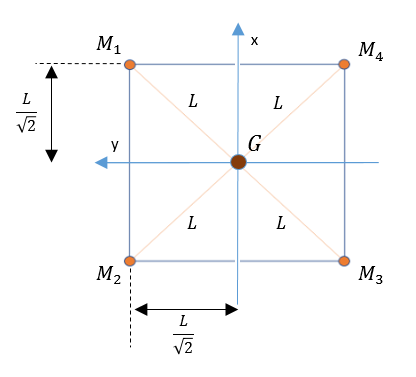     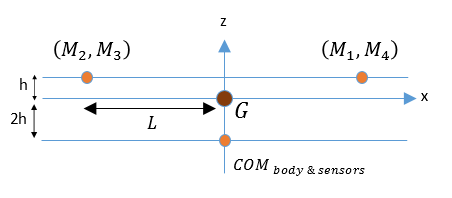

X0=[0,0,-2*h];      % [m] position of sensors
X1=[ L,L,h];        % [m] position of propeller 1
X2=[ L,-L,h];       % [m] position of propeller 2
X3=[-L,-L,h];       % [m] position of propeller 3
X4=[-L,L,h];        % [m] position of propeller 4

dm0=m/2;            % [kg] mass of sensors
dm1=m/8;            % [kg] mass propeller 1
dm2=m/8;            % [kg] mass propeller 2
dm3=m/8;            % [kg] mass propeller 3
dm4=m/8;            % [kg] mass propeller 4

% calcul des produits d'inertie
Ixy = X0(1)*X0(2)*dm0 + X1(1)*X1(2)*dm1 + X2(1)*X2(2)*dm2 + X3(1)*X3(2)*dm3 + X4(1)*X4(2)*dm4;
Iyx = Ixy; % par symétrie
Iyz = X0(3)*X0(2)*dm0 + X1(3)*X1(2)*dm1 + X2(3)*X2(2)*dm2 + X3(3)*X3(2)*dm3 + X4(3)*X4(2)*dm4;
Izy = Iyz; % par symétrie
Ixz = X0(1)*X0(3)*dm0 + X1(1)*X1(3)*dm1 + X2(1)*X2(3)*dm2 + X3(1)*X3(3)*dm3 + X4(1)*X4(3)*dm4;
Izx = Ixz; % par symétrie

% calculs des produits d'inertie
Ix2=X0(1)*X0(1)*dm0 + X1(1)*X1(1)*dm1 + X2(1)*X2(1)*dm2 + X3(1)*X3(1)*dm3 + X4(1)*X4(1)*dm4;
Iy2=X0(2)*X0(2)*dm0 + X1(2)*X1(2)*dm1 + X2(2)*X2(2)*dm2 + X3(2)*X3(2)*dm3 + X4(2)*X4(2)*dm4;
Iz2=X0(3)*X0(3)*dm0 + X1(3)*X1(3)*dm1 + X2(3)*X2(3)*dm2 + X3(3)*X3(3)*dm3 + X4(3)*X4(3)*dm4;
Ix=Iy2+Iz2;
Iy=Ix2+Iz2;
Iz=Ix2+Iy2;

I = [[Ix -Ixy -Ixz];...
     [-Iyx Iy -Iyz];...
     [-Izx -Izy Iz]];

% limitations / saturations
RP_angle_saturation = 0.25;     % [rad] limite sur le pitch/roll pour l'hypothèse des petits angles
prop_sat_up = inf;              % [rad/s] pas de limites de vitesses sur les moteurs (pour l'instant) 
prop_sat_down = -inf;           % [rad/s] pas de limites de vitesses sur les moteurs (pour l'instant) 